Kg=1;
Kt=2.3e-2;
Ke=Kt;
p=6.35e-3;
R=8.3;
K=Ke*Kg/(R*p);

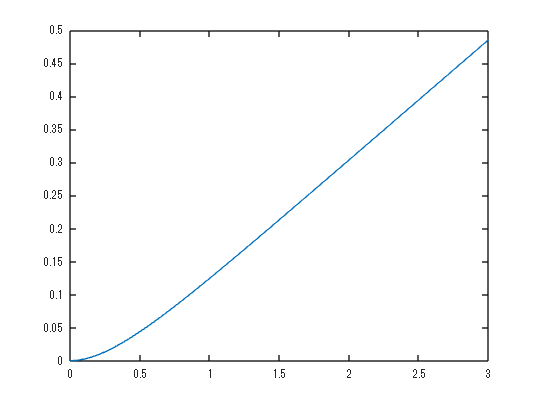

pos=data.cart_position;
time=data.time;
E=data.voltage(1);

plot(time,pos)

sz=size(time,1);
p=polyfit(time(int32(sz*3/4):end),pos(int32(sz*3/4):end),1)

p =     0.1817   -0.0597


Dx=1/(p(1)/(K*E))

Dx = 2.8818

M=(-p(2)/p(1))*Dx

M = 0.9473

l2=0.42;
l=l2/2;
m=0.057;
g=9.8;

time=data.time;
pos=data.pole_angle;

pos=pos-mean(pos);

x=[time(1)];
y=[pos(1)];
for i=2:size(time,1)-1
    if pos(i-1)<pos(i) && pos(i)>pos(i+1)
        x=[x;time(i)];
        y=[y;pos(i)];
    end
end

period=0;
for i=2:size(y,1)
    period=period+x(i)-x(i-1);
end
period=period/(size(x,1)-1)

period = 1.0611

w=2*pi/period

w = 5.9213


p=polyfit(x,log(y),1);
c=-p(1)

c = 0.0213

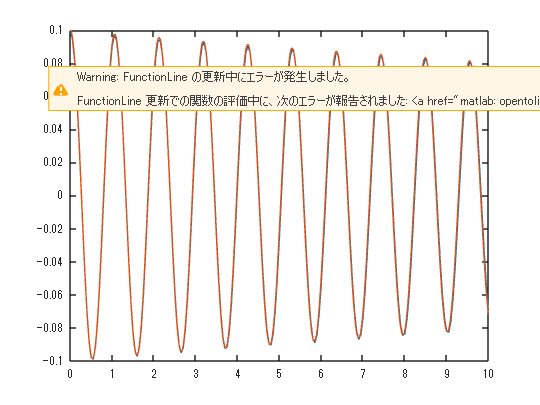



plot(time,pos)
hold on;
func=@(t) 0.1*exp(-c*t).*cos(w*t);
fplot(func,[min(time),max(time)])
hold off;


4/3*m*l.^2

ans = 0.0034

I=1/(w.^2+c.^2)*m*g*l

I = 0.0033

Dt=c*2*I

Dt = 1.4241e-04